# IMU Data Analysis

clear s
s = serialport("COM21", 9600)

s =   Serialport with properties:

                 Port: "COM21"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


ans = 2×1 string array
    "359.875"
    "0.4375"


ans = 0.3750

data_length = 10;
frequency = 10;
time = 0:(1/frequency):data_length

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


yaw = zeros(1, data_length);
pitch = zeros(1, data_length);

for i = 1:data_length*frequency
    yaw(i) = str2double(strip(s.readline()));
    pitch(i) = str2double(strip(s.readline()));
end

yaw =   359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375


pitch =     0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375


save 01_28_2025.mat yaw pitch

yaw

yaw =   359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375  359.9375


pitch

pitch =     0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375


yaw_velocity = diff(yaw)/(1/frequency)

yaw_velocity =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


pitch_velocity = diff(pitch)/(1/frequency)

pitch_velocity =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


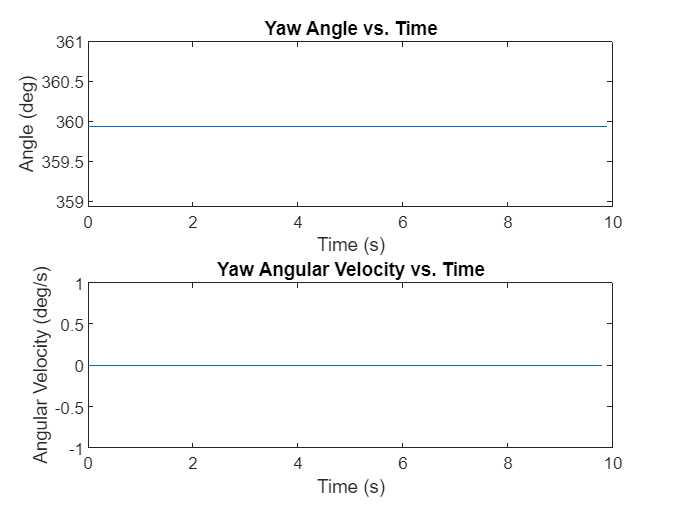


subplot(2,1,1)
plot(time(1:data_length*frequency), yaw)
title("Yaw Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (deg)")

subplot(2,1,2)
plot(time(1:data_length*frequency-1), yaw_velocity)
title("Yaw Angular Velocity vs. Time")
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")

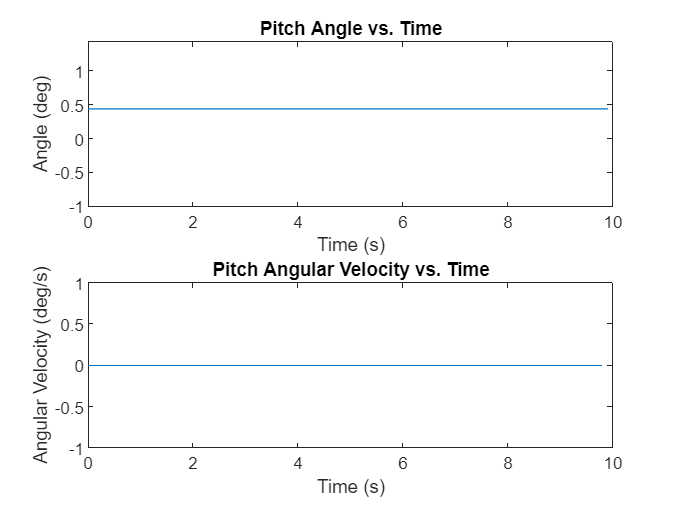

subplot(2,1,1)
plot(time(1:data_length*frequency), pitch)
title("Pitch Angle vs. Time")
xlabel("Time (s)")
ylabel("Angle (deg)")

subplot(2,1,2)
plot(time(1:data_length*frequency-1), pitch_velocity)
title("Pitch Angular Velocity vs. Time")
xlabel("Time (s)")
ylabel("Angular Velocity (deg/s)")